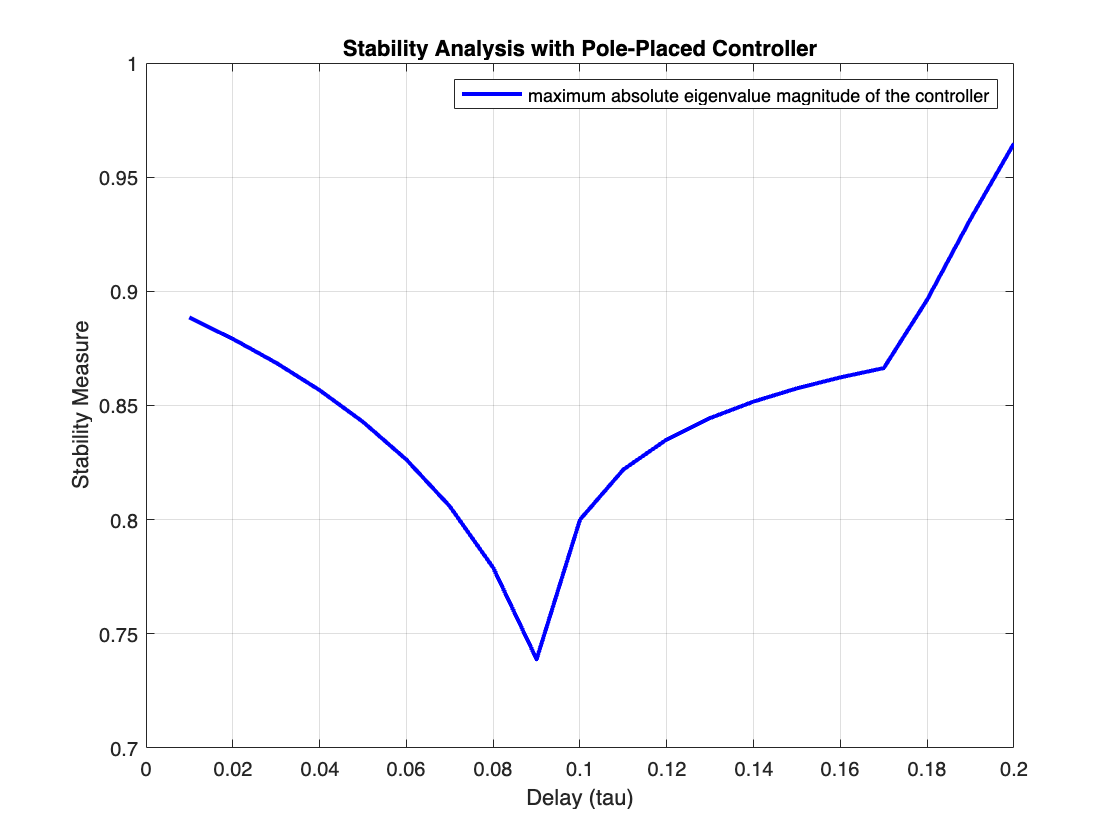

%% Pole placement
% Define the system matrices A and B based on the given system
a = 5;
b = 3;
c = 1;
A = [a-b, 0.5-c; 0, 1];
B = [0; 1];

% Define the selected sampling interval
h = 0.2;
%under no delay
tau1 = 0.1;

%system
Fx = expm(A*h);
Fu = (expm(A*h) - expm(A*(h-tau1)))/A * B;
G1 = (expm(A*(h-tau1)) - eye(size(A)))/A * B;
Fe1 = [Fx, Fu; zeros(1,2) zeros(1)];
Ge1 = [G1; 1];

% Desired closed-loop poles
desired_poles = [0.5, 0.4, 0.8];

% Compute the feedback gain matrix K using pole placement
K = place(Fe1, Ge1, desired_poles);

% Compute the closed-loop system matrix with the pole-placed controller
Acl1 = Fe1 - Ge1*K;

% Check stability of the closed-loop system
eigvals1 = eig(Acl1);

% Calculate stability for different delay values
tau_values = 0.01:0.01:h;
stab_values = zeros(size(tau_values));

for i = 1:length(tau_values)
    tau = tau_values(i);
    Fx = expm(A*h);
    Fu = (expm(A*h) - expm(A*(h-tau)))/A * B;
    G1 = (expm(A*(h-tau)) - eye(size(A)))/A * B;
    Fe = [Fx, Fu; zeros(1,2) zeros(1)];
    Ge = [G1; 1];

    % Compute the closed-loop system matrix with the pole-placed controller
    Acl = Fe - Ge*K;

    % Check stability of the closed-loop system
    eigvals = eig(Acl);
    max_eigval = max(abs(eigvals));
    stab_values(i) = max_eigval;
    
end

% Plot stability measure against delay (tau)
plot(tau_values, stab_values, 'b-', 'LineWidth', 2);
xlabel('Delay (tau)');
ylabel('Stability Measure');
title('Stability Analysis with Pole-Placed Controller');
legend('maximum absolute eigenvalue magnitude of the controller')
grid on;

%% LMI
% Define the selected sampling interval
h1 = 0.5;
%under no delay
tau = linspace(0.01, 0.048, 15);


x = sdpvar(3,3); % x = inv(P)
y = sdpvar(1,3); % y = K*inv(P), dim(K) = dim(y)


con2 = [x >= eye(3,3)^-10];
for i =1:length(tau)
    Fx = expm(A*h1);
    Fu = (expm(A*h1) - expm(A*(h1-tau(i))))/A * B;
    G1 = (expm(A*(h1-tau(i))) - eye(size(A)))/A * B;
    Fe = [Fx, Fu; zeros(1,2) zeros(1)];
    Ge = [G1; 1];
% Check stability using LMIs(for discrete-time case)
con1 = [[x, Fe*x-Ge*y; x*(Fe)'-(Ge*y)', x] >= 0];
cons = [con1, con2];
options = sdpsettings('solver', 'sedumi');
sol = optimize(cons, [], options);
end

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 9, order n = 10, dim = 46, blocks = 3
nnz(A) = 42 + 0, nnz(ADA) = 81, nnz(L) = 45
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.05E+00 0.000
  1 :   0.00E+00 8.46E-01 0.000 0.2088 0.9000 0.9000  -0.62  1  1  5.2E+00
  2 :   0.00E+00 1.72E-01 0.000 0.2034 0.9000 0.9000  -0.62  1  1  4.1E+00
  3 :   0.00E+00 1.13E-02 0.000 0.0657 0.9900 0.9900  -0.79  1  1  2.3E+00
  4 :   0.00E+00 2.77E-03 0.000 0.2449 0.9000 0.9000   0.06  1  1  8.2E-01
  5 :   0.00E+00 1.95E-04 0.000 0.0703 0.9900 0.9900   0.76  1  1  6.4E-02
  6 :   0.00E+00 1.48E-05 0.000 0.0761 0.9900 0.9900   0.98  1  1  4.9E-03
  7 :   0.00E+00 1.09E-06 0.000 0.0739 0.9900 0.9900   1.00  1  1  3.6E-04
  8 :   0.00E+00 8.04E-08 0.000 0.0735 0.9900 0.9900   1.00  1  1  2.7E-05
  9 :   0.00E+00 5.90E-09 0.000 0.0733 0.9900 0.9900   1.00  1  1  2.0E-06
 10 :   0.00E+00 


if sol.problem == 0
    disp('The sampled-data controller is stable.');
    X = value(x)
    Y = value(y)
    K = Y * inv(X)
else
    disp('The sampled-data controller is unstable.');
end

The sampled-data controller is stable.


X =    11.2467   47.6318  -14.4802
   47.6318  244.8561 -142.4145
  -14.4802 -142.4145  895.9773


Y =    50.9965  365.0242 -227.0231


K =   -11.1971    3.7643    0.1640


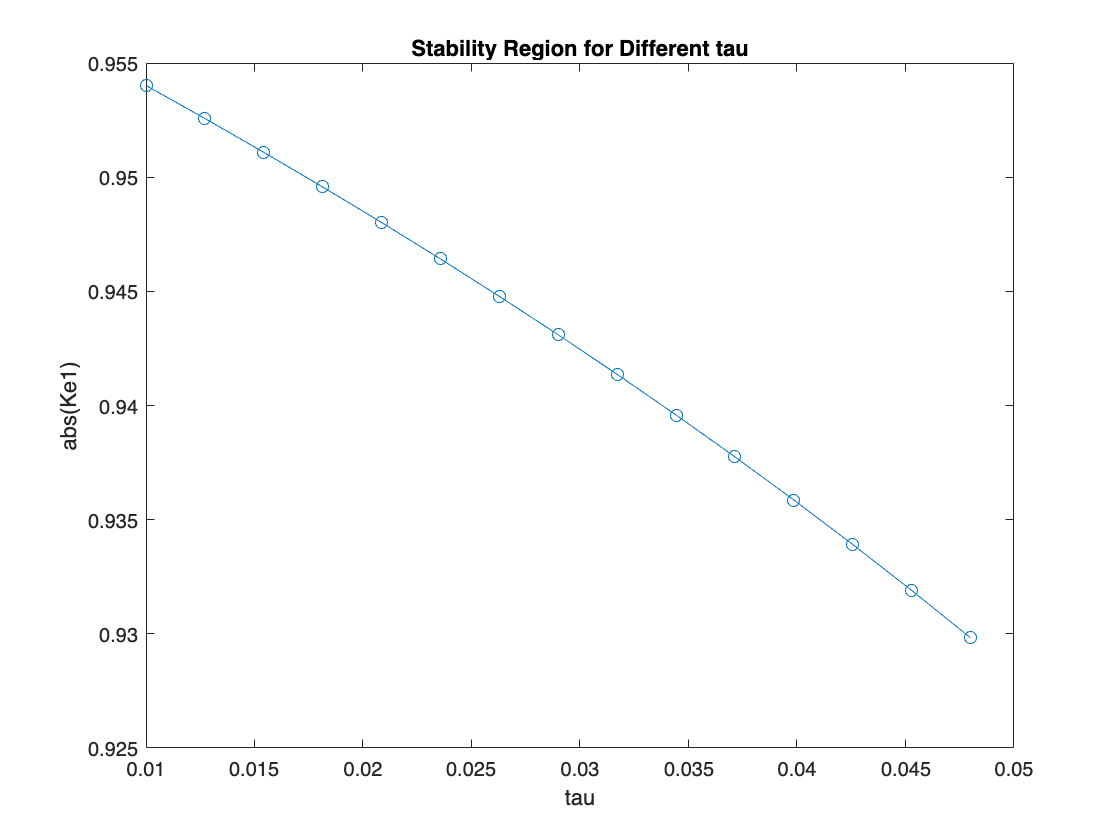

Ke1 = Fe - Ge*K;
eig(Ke1); %stable

% Plot
result = zeros(size(tau));
for i = 1:length(tau)
    % When 0 <= tau < h
        Fx = expm(A*h);
        Fu = (expm(A*h) - expm(A*(h-tau(i))))/A * B;
        G1 = (expm(A*(h-tau(i))) - eye(size(A)))/A * B;
        Fe = [Fx, Fu; zeros(1,2) zeros(1)]; 
        Ge = [G1; 1];
    
    Ke1 = Fe - Ge*K;
    result(i) = max(abs(eig(Ke1))) ;
    %result(i) = max(abs(eig(Ke1))) < 1; %it should be all '1'
end

% Plotting
plot(tau, result, 'o-');
xlabel('tau');
ylabel('abs(Ke1)');
title('Stability Region for Different tau');